**Model of car turn using Ackerman geometry**

% Dimensions (cm)
k_arm = 10;     % arm connected to knuckle 
t_rod = 21;   % intermediate arm
rack = 35;
track = 80;    % wheelbase width
d = 18.72;     % Distance between rack & front chassis
tire = 15; 

% Angles
alpha = 22;  % Angle between tire and knuckle arm (fixed angle)
steer = -15;   % Steering angle
beta = 90 - alpha + steer;  % whole angle between tire and front chassis

% Data of plot
figure(); title('Steering model')
hold on; grid on; xlim([-250 50]); ylim([-180 120]);
plot(0, 0, 'bo', MarkerSize=5);

% Track
plot(-track/2, d, 'ro', MarkerSize=5);
plot(track/2, d, 'ro', MarkerSize=5);
plot([-track/2, track/2], [d,d], 'k', LineWidth=2);
% Dist
plot(0, d, 'ro', MarkerSize=5);
plot([0, 0], [d, 0], 'k', LineWidth=1.5, LineStyle='--');

% Inner tire (in turn)
tire_point = [-track/2 + (tire/2) * cos(deg2rad(steer + 90)), d - (tire/2) * sin(deg2rad(90 + steer))];
tire_point_up = [-track/2 - (tire/2) * cos(deg2rad(steer + 90)), d + (tire/2) * sin(deg2rad(90 + steer))];
% Plot right wheel
plot(tire_point(1), tire_point(2), 'ko', MarkerSize=2.5);
plot(tire_point_up(1), tire_point_up(2), 'ko', MarkerSize=2.5);
plot([tire_point(1), tire_point_up(1)], [tire_point(2), tire_point_up(2)], LineWidth=2, Color='k')
% Steering wheel angle line (vertical)
plot([-track/2, -track/2], [d, d+20], LineStyle='--', LineWidth=1, color='k')

% Ending tie rod (begin of knuckle arm)
tie_rod = [-track/2 + k_arm * cos(deg2rad(beta)), d - k_arm * sin(deg2rad(beta))];
plot(tie_rod(1), tie_rod(2), 'bo', MarkerSize=2);
plot([-track/2, tie_rod(1)], [d, tie_rod(2)], LineWidth=2, Color='k');

% Tie rod calculations (cosines)
B = tie_rod(2); % take the vertical distance to origin of that point
C = t_rod;      % hypotenuse = tie rod length
A = sqrt(C^2 - B^2);  % Pythagorean
gamma_l = rad2deg(acos((A^2 + C^2 - B^2) / (2 * A * C))) % Cosine law to get angle between rack and horizontal

gamma_l = 30.7389

in_mid = 270 - (90 - gamma_l) - beta  % Mid angle (k_arm / tie rod)

in_mid = 157.7389

rack_l = [tie_rod(1) + t_rod * cos(deg2rad(in_mid - (180 - beta))), tie_rod(2) - t_rod * sin(deg2rad(in_mid - (180 - beta)))];
plot(rack_l(1), rack_l(2), 'bo', MarkerSize=2);
plot([tie_rod(1), rack_l(1)], [tie_rod(2), rack_l(2)], LineWidth=2, Color='k');

% Rack
rack_r = [rack_l(1) + rack, 0];
plot(rack_r(1), rack_r(2), 'ko', MarkerSize=2);
plot([rack_l(1), rack_r(1)], [0, 0], LineWidth=2, color='k')

**The next part is for the right section of the steering mechanism**

The angles and sides obtained here are base merely on the cosines law

% Calculate hypothenuse of rect triangle formed by right rack and vertical distance between rack and track
C = sqrt(rack_r(1)^2 + d^2);
% Now we have the 3 sides of that triangle so we can use cosine law to get all the angles
theta = acos((rack_r(1)^2 + C^2 - d^2) / (2 * rack_r(1) * C));
% Lets focus on the triangle formed by the previous hypothenuse, right track width and a imaginary line between rack right end and track right end
% We know two sides and an angle (theta because of hypothenuse being between rack and track wwhich are parallel to each other
% So lets use law of cosines to get the third side, lets call it k
w = track/2;  % For shorter name
k = sqrt(C^2 + w^2 - 2 * C * w * cos(theta));
% Now that we have the 3 sides we can calculate all the angles inside that triangle, lets calculate the one in the vertex of the tie rod
omega = rad2deg(acos((k^2 + C^2 - w^2) / (2 * k * C)));
% Finally lets focus on the remaining triangle (formed by tie rod, knuckle arm and k)
% we know the 3 sides, so its possible to calculate the angle in the same vertex of omega and theta
gam = rad2deg(acos((t_rod^2 + k^2 - k_arm^2) / (2 * t_rod * k)));
% Now the angle we need is the one that the tie rod forms with the x axis
% (outer angle) which is suplementary to theta + omega + gam
gamma_r = deg2rad(180 - (rad2deg(theta) + omega + gam));

With this done, it is possible to locate the endpoint of the right tie rod and the knuckle arm

% Point in the plane
right_tie_point = [rack_r(1) + t_rod * cos(gamma_r), t_rod * sin(gamma_r)];
plot(right_tie_point(1), right_tie_point(2), 'bo', MarkerSize=1.5);

% Draw tie rod
plot([rack_r(1), right_tie_point(1)], [rack_r(2), right_tie_point(2)], LineWidth=2, Color='k');

% Draw right knuckle arm
plot([right_tie_point(1), track/2], [right_tie_point(2), d], LineWidth=2, color='k');

**Draw right wheel**

For drawing the wheel, the law of cosines is also used.

We know the angle between the bottom part of the tire with the knuckle arm, the length of the knuckle arm and also the length of the tire (one side is the tire length / 2). 

We are going to use the same triangles of the last operations to calculate the angle that is formed between the track and the left knuckle arm. This angle is the sum of the angles  formed by sides w-k and k-b.

% Steering wheel angle line (vertical)
plot([track/2, track/2], [d, d+20], LineStyle='--', LineWidth=1, color='k');
% Angle between sides w-k
a1 = rad2deg(acos((k^2 + w^2 - C^2) / (2 * w * k)))

a1 = 41.8067

a2 = rad2deg(acos((k_arm^2 + k^2 - t_rod^2) / (2 * k_arm * k)))

a2 = 37.1605

beta_right = a1 + a2  % The inner angle between track and knuckle_arm

beta_right = 78.9672

beta_right = deg2rad(beta_right + alpha)

beta_right = 1.7622


% Plot wheel
plot(track/2 + abs((tire/2) * cos(beta_right)), d - abs((tire/2) * sin(beta_right)), 'ko', MarkerSize=2);  % Lower point
plot(track/2 - abs((tire/2) * cos(beta_right)), d + abs((tire/2) * sin(beta_right)), 'ko', MarkerSize=2);
plot([track/2 + abs((tire/2) * cos(beta_right)), track/2 - abs((tire/2) * cos(beta_right))], ...
    [d - abs((tire/2) * sin(beta_right)), d + abs((tire/2) * sin(beta_right))], LineWidth=2, color = 'k');

Draw other lines

car_length = 70;

% Plot centerline
plot([0, 0], [d, -car_length], LineWidth=2, color='k', LineStyle='--');
% Plot rear wheels axis
plot([-track/2, track/2], [-car_length, -car_length], LineWidth=2, color='k');
% Plot rear wheels
plot([-track/2, -track/2], [-car_length - tire/2, -car_length + tire/2], LineWidth=2, color = 'k');
plot([track/2, track/2], [-car_length - tire/2, -car_length + tire/2], LineWidth=2, color = 'k');
% Plot rear wheel axis prolonged
plot([-250, track/2], [-car_length, -car_length], LineWidth=2, color='k', LineStyle='--');

% Get the line perpendicular to the inner wheel in the turn
slope = (tire_point_up(2) - tire_point(2)) / (tire_point_up(1) - tire_point(1));
% Get the reciprocal since it represents the slope for a perpendicular line
% to it 
recip = 1 / slope;
y = d; step = 0.1; count = 0;
while y > -car_length
    y = d + recip * count;
    count = count + 0.1;
end
count + track/2

ans = 371.3000

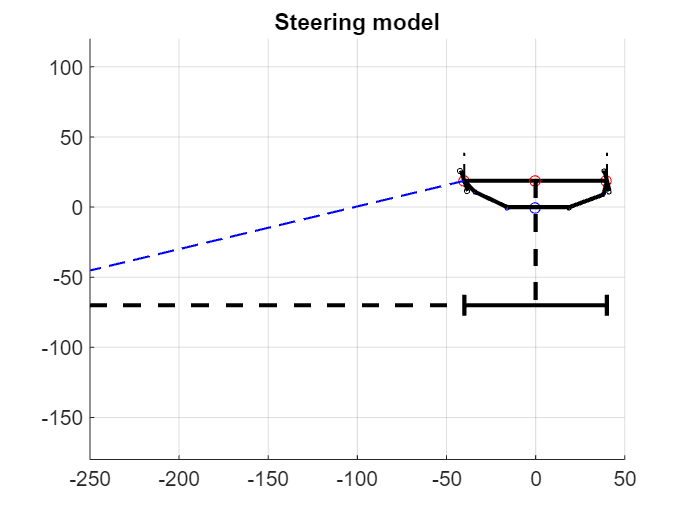

plot([-count, -track/2], [-car_length, d], LineWidth=1, LineStyle='--', color='b');